## **Driver test program to check Clothoids library**

**Test clothoid**

% check constructors
x0     = 0;
y0     = 2;
theta0 = 0;
kappa0 = -0.6;
x1     = 3;
y1     = 2;
theta1 = 0;
kappa1 = 0.6;
s0 = 0.5;
s1 = 0.5;
C1     = ClothoidList();
C2     = ClothoidList();

C1.build_3arcG2( x0, y0, theta0, kappa0, x1, y1, theta1, kappa1 );
C2.build_3arcG2fixed( s0, x0, y0, theta0, kappa0, s1, x1, y1, theta1, kappa1 )

ans = int64
   3


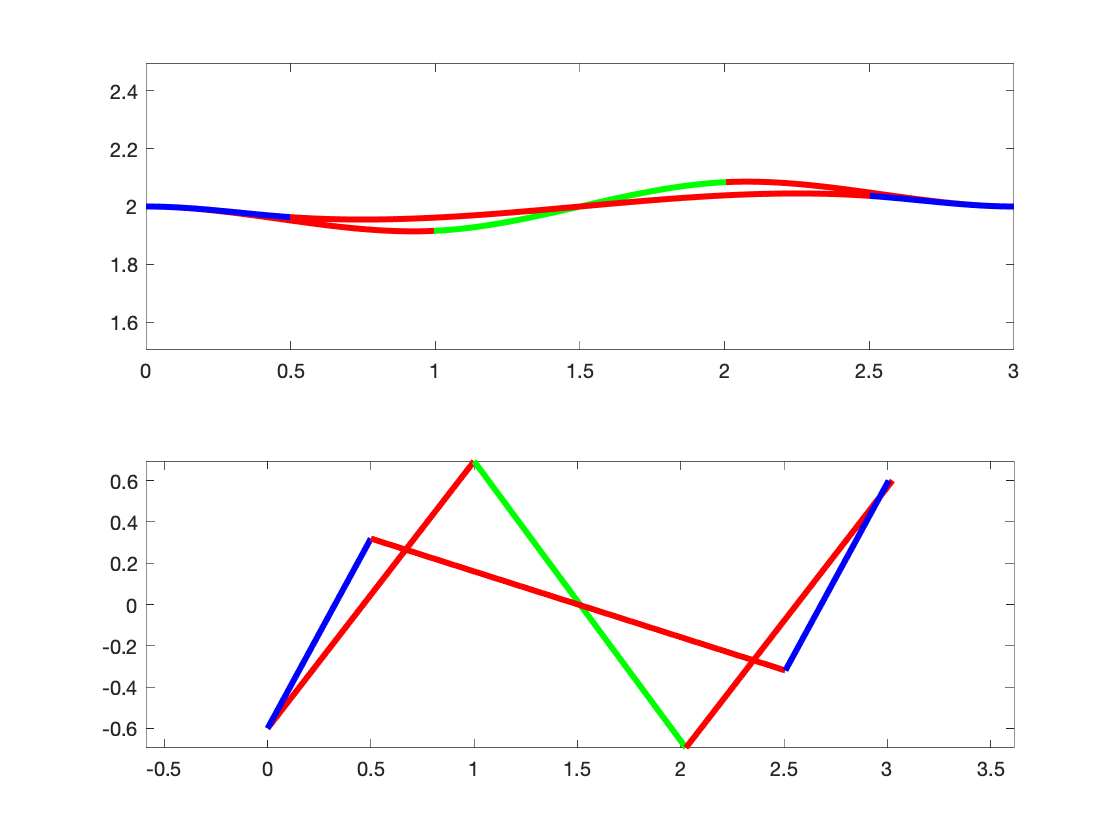


fmt1 = {'Color','green','LineWidth',3 };
fmt2 = {'Color','red','LineWidth',3 };
fmt3 = {'Color','blue','LineWidth',3 };

subplot(2,1,1);
C1.plot(1000,fmt1,fmt2);
hold on;
C2.plot(1000,fmt2,fmt3);
axis equal;

subplot(2,1,2);
C1.plotCurvature(1000,fmt1,fmt2);
hold on;
C2.plotCurvature(1000,fmt2,fmt3);
axis equal;


%
C1.delete();
C2.delete();